# Task_00:    **Define car model parameters**

Consider the car system shown below

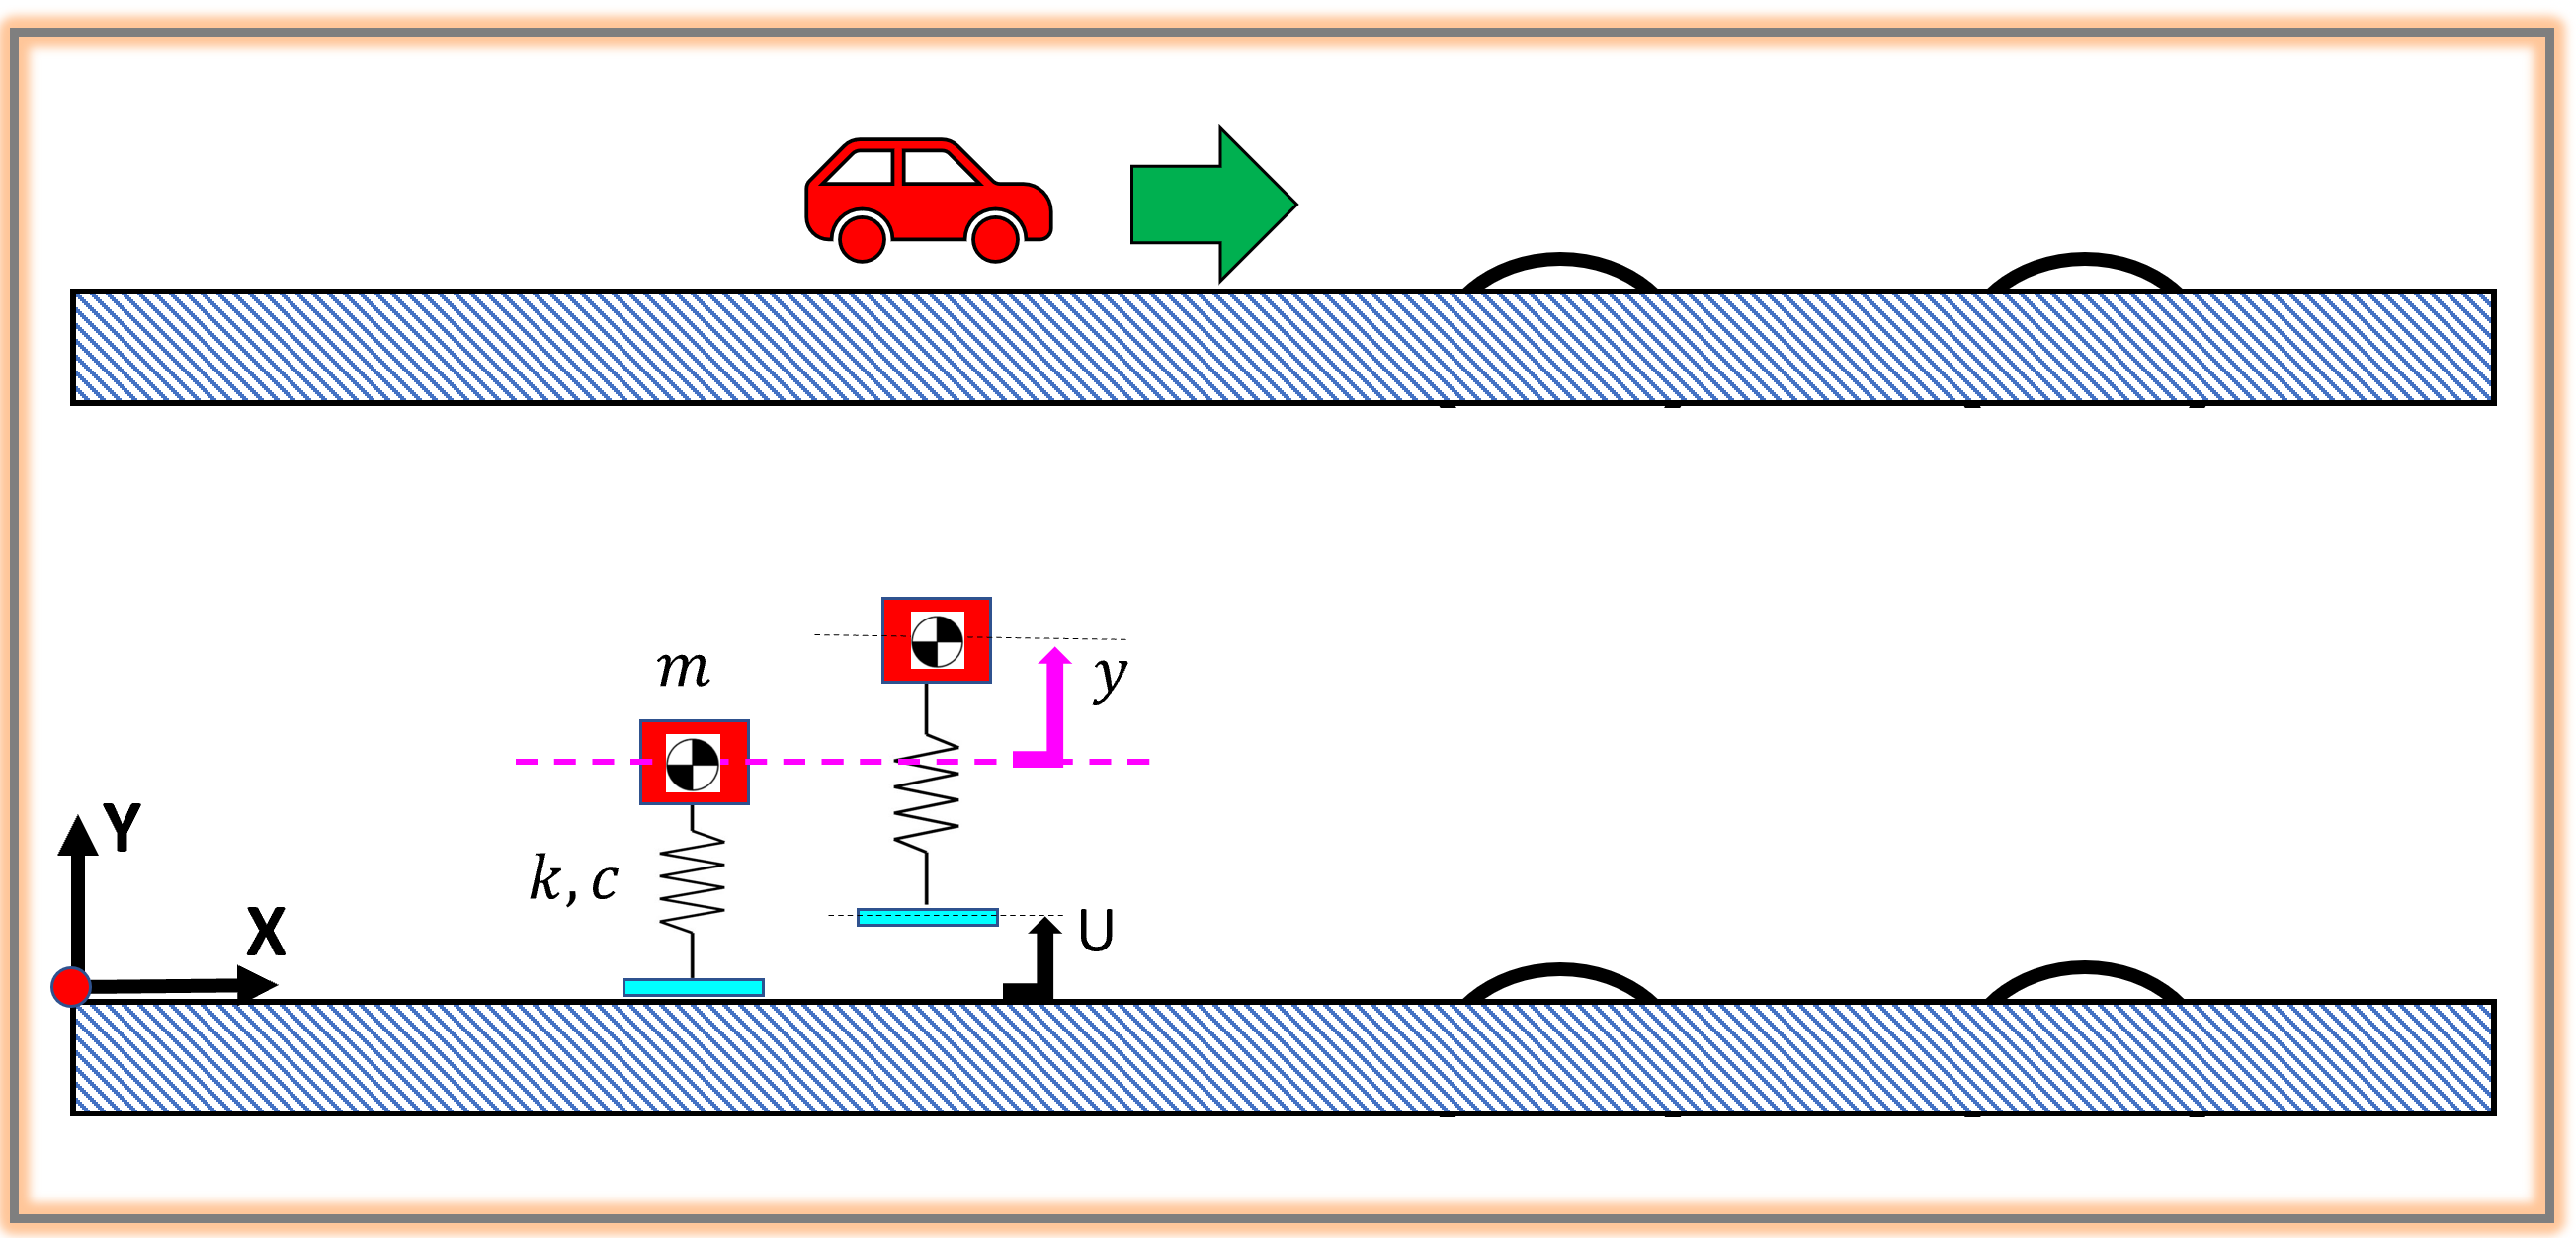

**NOTE:**

- $m\;:\;\;$mass   *(kg)*

- $k\;:\;\;$spring stiffness co-eficient   *(N/m)*

- $c\;:\;\;$spring damping co-efficient   *(N/(m/s))*

- $y\;:\;\;$displacement of mass from equilibrium position   *(m)*

- $U\;:\;$road displacement   *(m)*

### Some Environment parameters

Although the gravitational constant $g$ does NOT appear in the derived equations of motion, it is a parameter that needs to be set inside Simscape .... so we'll create the following parameter:

env_T.g_vec = [0,0,0];

### Some PLANT parameters

plant_T.m = 5.0;       % (kg)
plant_T.k = 500;       % (m)
plant_T.c = 2*10*0.6;  % (N.m/(m/sec))

### Define the Car's Initial conditions - for NEWTON

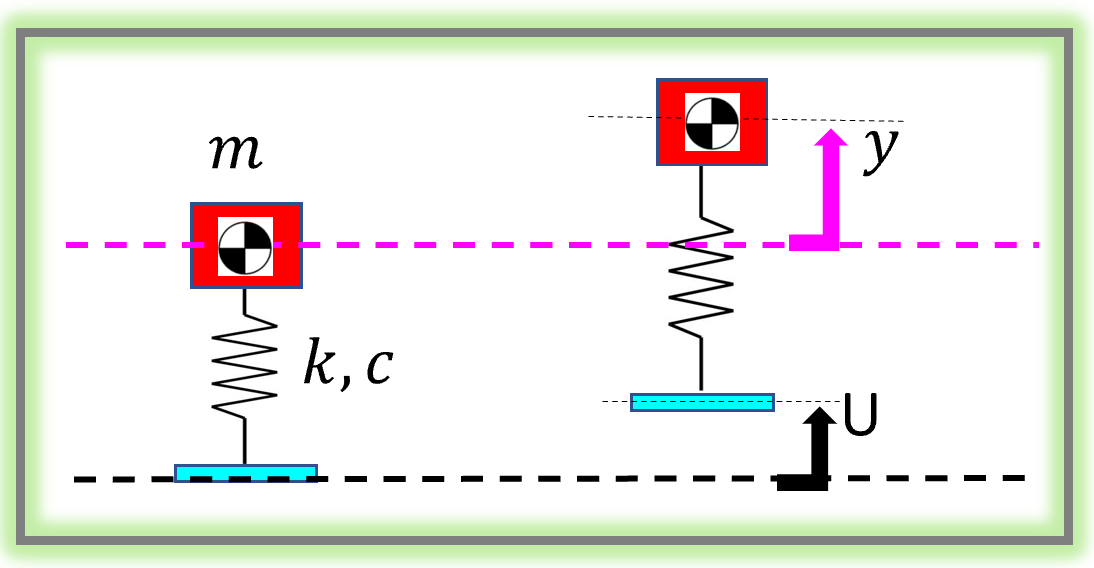

IC_T.y        = 0;  % (m)    <---- specify this
IC_T.y_dot    = 0;  % (m/s)  <---- specify this

### Define the Car's Initial conditions - for Simscape

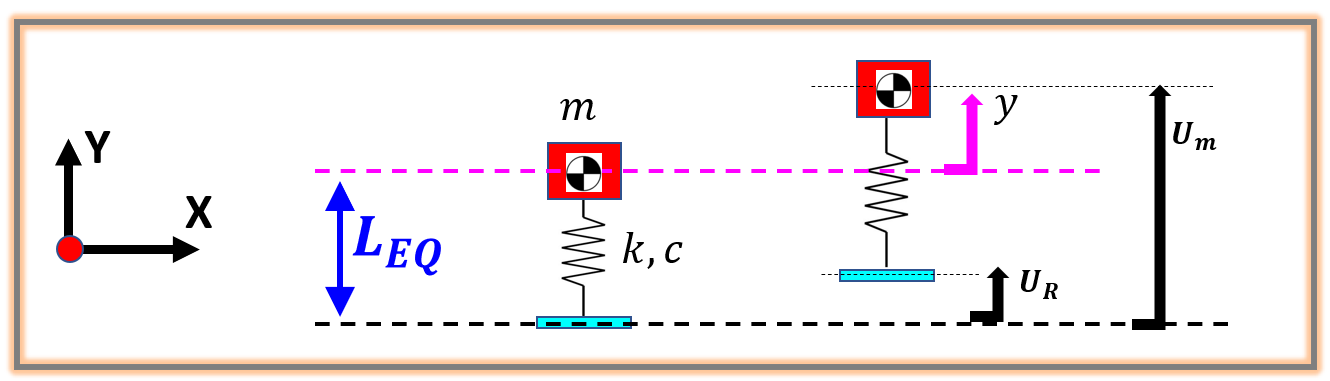

IC_T.L_EQ    = 1.0;                  % (m) - the UNstretched spring length
IC_T.U_m     = IC_T.L_EQ  + IC_T.y;  % (m)
IC_T.U_m_dot = IC_T.y_dot;           % (m)

IC_T.U_R      = 0;  % (m)  <---- specify this
IC_T.U_R_dot  = 0;  % (m)  <---- specify this

IC_T.U_m_rel_R     = IC_T.U_m - IC_T.U_R;         % ###_###: needed by the SIMSCAPE Multibody model
IC_T.U_m_rel_R_dot = IC_T.U_m_dot - IC_T.U_R_dot; % ###_###: needed by the SIMSCAPE Multibody model